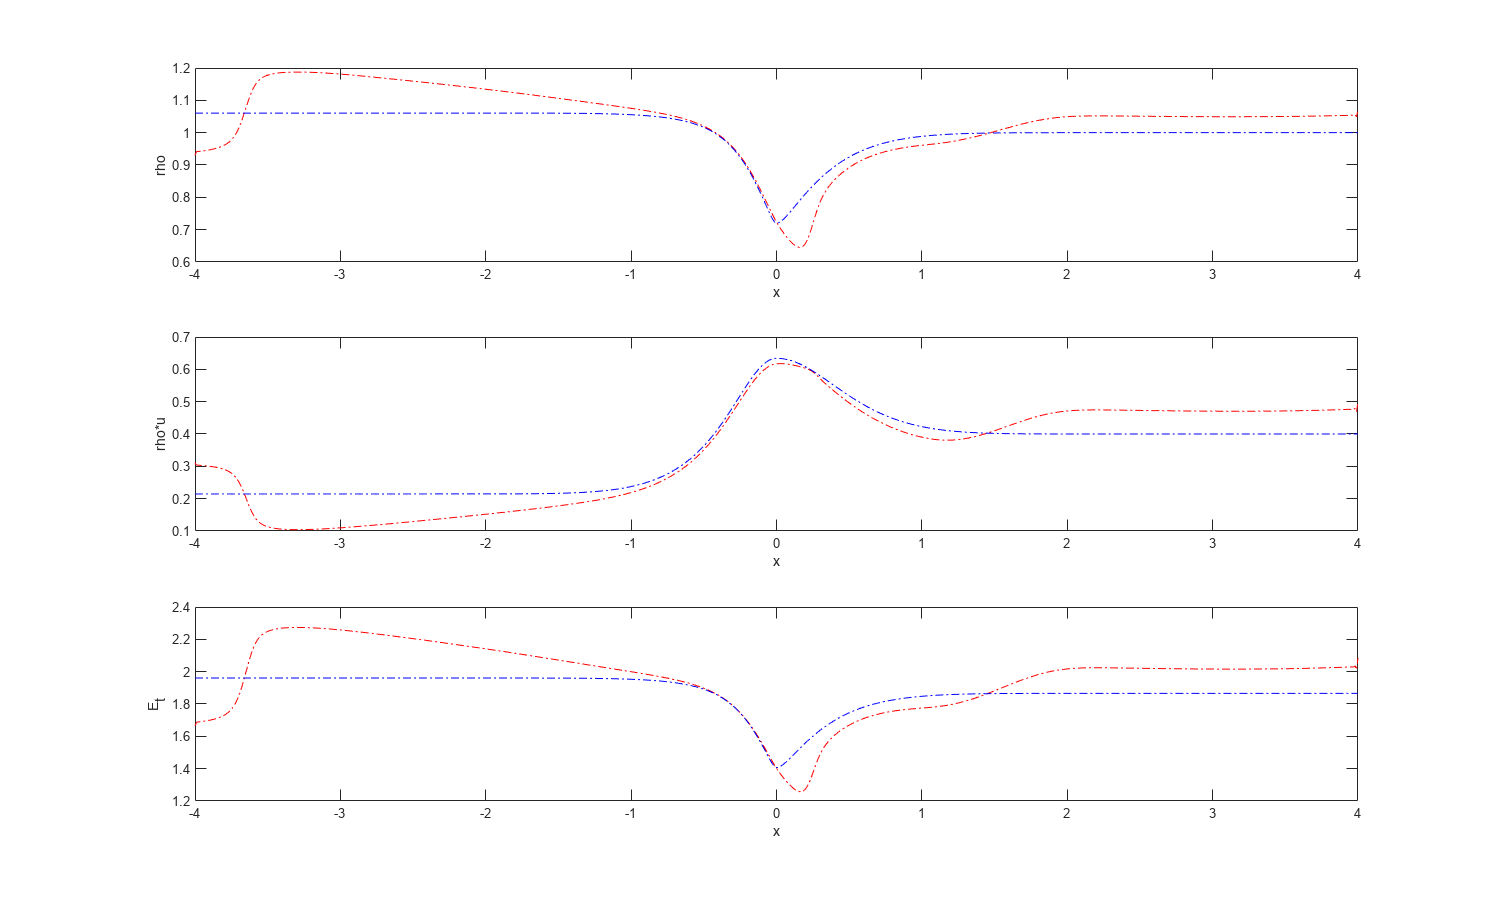

   14.8615

   12.4037

   10.5683

    9.8796

    9.9345

   10.1647

   10.3123

   10.3139

   10.0806

    9.2579

    8.1353

    9.3812

   10.4841

   10.8222

   10.9897

   11.1329

   11.3233

   11.6168

   12.0123

   12.3229

   11.8750

    9.9458

    9.4992

    9.6546

    9.9637

   10.2807

   10.5965



   10.9159



clear; close; clc;



% strecch goals:
% local time stepping - done
% use all 3 characteristics
% van lee limiter
% lax freedrich flux
% SSP-RK4

% 3/11/2023 DEGUB NOTES:
% works with no sorouce terms blows up otherwise
% pressure goes complex cuaseing problems
% is suspect issue is with indexing
% spikyness propagating backwards from edgeindicating possible issue with
% rusanov flux or reinman solver 

% 4/11/2023 DEGUB NOTES:
% if IC set to outlet then the solution starts to propagare from left as
% expected only when if hits the right boundary does the spiky start and
% residual increase
% issue was order of the terms in imput to rienmann flux function

% define parameters

order = 1;
limiter = 0;
cfl = .25; % work out this
%steps = 2000
x_min = -4;
x_max = 4;
gamma = 1.4;
flow = 1; % defines problem 1 or 2
isGlobal = true; % use global time stepping
simpleBC = false; % use simple boundary conditions?


%numCells = 100; % number of cells
numCells = 800; % number of cells
%numCells = 5; % For Debug (this should work - it currently goes complex and should be hand calculable)
numFaces = numCells + 1; % number of faces

% solution arrays
Q_star = zeros(3,numCells);
Q = ones(3,numCells);


% boundary values (simple)
Q_inlet = zeros(3,1);
Q_outlet = zeros(3,1);


Initialize(flow);
Q_inlet = ExactSolu(x_min, flow);
Q_outlet = ExactSolu(x_max, flow);

%assign the initial condition to be outlet (this needed to prevent
%trainsent shock formation which will break the code without a limiter)
Q = repmat(Q_outlet,1,numCells);


% FOR DEBUG
%  Q_inlet = [1; 1; 1];
%  Q_outlet = [1; 1; 1];


% problem geometery
Delta_x = (x_max-x_min) / (numCells-1);

x_points = x_min:Delta_x:x_max; % x locations
%x_points = linspace(-4,4,numCells); % x locations (this puts a point at the BC which is not strictly correct)

A = area(x_points); % area
dAdx = gradient(A,x_points); % derivative of area with respect to horizontal position

Delta_x = x_points(2) - x_points(1);

% compute exact solution for comparision
Q_exact = zeros(3,numCells);
for i = 1:numCells
    Q_exact(:,i) =  ExactSolu(x_points(i),flow);
end

% create firue for plots
figure(Position=[1,1,1500,900]);

% setup for loop
res_initial = Residual(Q, Q_inlet, Q_outlet, Delta_x, gamma, A, dAdx, order); % not ture but a guess to use for convergence (for now)

converged = false;

itteration = 0;

while converged == false
    itteration = itteration + 1;

    %dt = %calculateTimeStep
%    Delta_t = .001; % rough estimate for testing (100 200 400 steps will work)
%    Delta_t = .00001; % rough estimate for testing (100 200 400 steps will work)
    %Delta_t = .01; % rough estimate for testing (100 200 400 steps will work)
    %TODO: compute timestepsize
    Delta_t = computeTimeStep(Delta_x, cfl, Q, gamma, isGlobal);

    S = getSlope(Q, Q_inlet, Q_outlet, Delta_x, order);
   

    % SSP-RK2
    res_old = Residual(Q, Q_inlet, Q_outlet, Delta_x, gamma, A, dAdx, order);
    Q_star = Q + Delta_t .* res_old; % intermediate step

    res_star = Residual(Q_star, Q_inlet, Q_outlet, Delta_x, gamma, A, dAdx, order);
    Q = .5 * (Q + Q_star + Delta_t .* res_star); % final step

    % test convergence
    if abs(norm(res_star)) <= abs(norm(res_initial) * 1E-6)
        %break;
        converged = true;
        break;
    end

    %plotting
    if mod(itteration,100) == 0 %plot only every hundreth itteration
        plotState(x_points, Q);
        hold on;
        plotWithExactSoln(x_points,Q,Q_exact);
        hold off;
        clc; disp(norm(res_star));
        %plotThermo(x_points, Q, gamma); % for debug
        drawnow;
    end
end

function res = Residual(Q, Q_inlet, Q_outlet, Delta_x, gamma, A, dAdx, order)
    %NOTE TO SELF: when implementing in the n dimentional case replace F_L
    %and F_R as fluxes assumed positive in (flip order of F_R arguments)
    %then summ fluxes in (note F_R would look like a negivte flux in
    %meaning flux out) thus simplifiying implementation using connectivity
    %matrix and generalizing

    S = getSlope(Q, Q_inlet, Q_outlet, Delta_x, order); % estimate the slope (recontrution)

    Q_triangle = Q - 1/2 * Delta_x * S; % value at left boundary of cv
    Q_square = Q + 1/2 * Delta_x * S; % value at right boundary of cv
    
    Q_triangle_ip1 = [Q_triangle(:,2:end), Q_outlet]; % value at left boundary of cv plus 1 index (Q_tirangle_i+1)
    Q_square_im1 = [Q_inlet, Q_square(:,1:end-1)]; % value at right boundary of cv minus 1 index (Q_square_i-1)


    % fluxes on contol volume baoundaries
    F_L = RienmannSolver(Q_triangle, Q_square_im1, gamma);
    F_R = RienmannSolver(Q_triangle_ip1, Q_square, gamma);

    % compute residual
    res = (F_L - F_R) ./ Delta_x + getSource(Q, gamma, A, dAdx); % this should be correct
    %res = (F_L - F_R) ./ Delta_x - getSource(Q, gamma, A, dAdx); % might fix blow up (worked for jackson)
end

function Flux = RienmannSolver(Q_L, Q_R, gamma)
    %NOTE TO SELF: when implementing in the n dimentional case define
    %instead with flux in and flux out (rather than left and right) with
    %sign convetion positive in (EQUIVALENT TO CURRENT IMPLEMENTAITON)
    f_L = getFlux(Q_L, gamma);
    f_R = getFlux(Q_R, gamma);

    [u_L, ~, ~, ~, c_L] = getFlowProperties(Q_L, gamma);
    [u_R, ~, ~, ~, c_R] = getFlowProperties(Q_R, gamma);
    
    russanovFlux = abs((u_L + u_R) / 2 + (c_L + c_R) / 2)/2 .* (Q_L - Q_R); % this technically correct as well
    %russanovFlux = (abs((u_L + u_R)) / 2 + (c_L + c_R) / 2)/2 .* (Q_L - Q_R); % this is what it should be
    

    Flux = (f_L + f_R) / 2 - russanovFlux/2; % this should be correct
    %Flux = -(f_L + f_R) / 2 - russanovFlux;
end

function slope = getSlope(Q, Q_inlet, Q_outlet, Delta_x, order)
    if order == 2 % linear slope
        slope = ([Q(:,2:end), Q_outlet] - [Q_inlet, Q(:,1:end-1)]) / (2*Delta_x);
    elseif order == 1 % assume constnat
        slope = 0;
    else % we only support order 1 and 2 accuracy
        fprintf("Order %g not supported.", order);
    end
end


function [u, p, E, rho, c] = getFlowProperties(Q, gamma) % checked - not confident (ok?)
    % get thermodynamic properties of flow from state vector Q
    rho = Q(1,:);
    u = Q(2,:) ./ Q(1,:);
    p = (Q(3,:) - 1/2 .* Q(2,:).^2./Q(1,:)) * (gamma - 1); % currently p is going negative sometimes
    E = Q(3,:);
    c = sqrt(gamma*p./rho); % given by josh sutton and jackson (this is correct)
    
    % FOR DEBUG
    if sum(rho < 0) > 0
        disp("negative rho There is a bug")
    end
    if sum(p < 0) > 0
        disp("negative p There is a bug")
     end
    if sum((gamma*p./rho) < 0) > 0
        disp("complex spd sound There is a bug")
    end
    %c = 1; % FOR DEBUG
end

function [G] = getSource(Q, gamma, A, dAdx) % checked
    [u, p, E, rho, ~] = getFlowProperties(Q, gamma);

    G = zeros([3,length(rho)]);
    G(1,:) = -rho .* u .* 1./A .* dAdx;
    G(2,:) = -rho .* u.^2 .* 1./A .* dAdx;
    G(3,:) = -u .* (E+p) .* 1./A .* dAdx;

    %G = zeros([3,length(rho)]); % FOR DEBUG
end

function [F] = getFlux(Q, gamma) % checked
    [u, p, E, rho, ~] = getFlowProperties(Q, gamma);
    
    F = zeros([3,length(rho)]);
    F(1,:) = rho .* u;
    F(2,:) = rho .* u.^2 + p;
    F(3,:) = u .* (E+p);
end

function Delta_t = computeTimeStep(Delta_x, CFL, Q, gamma, isGlobal)
    % NOTSE TO SELF: when implementing differing wave speeds:
    % Delta_t = CFL * Delta_x / c where c is wave speed chosen from the 3
    % waves speed to minimize delta t (which is u + c)

    % global time steing followis physical path local time stepping
    % converges faster to equibrium solution
    [u_1, ~, ~, ~, c_1] = getFlowProperties(Q,gamma); % subscript 1 is to prevent u and c become global variables
    
    Delta_t = CFL * Delta_x ./ abs(u_1+c_1);

    if(isGlobal) % Use Global time stepping (physical)
        % globaltime step is defined by the smallest local timestep
        Delta_t = repelem(min(Delta_t),length(Delta_t));
    end % otherwise Use local time steps (non physical)
end

function plotState(x_points, Q)
    % Plot the conserved variables
    subplot(3,1,1);
    plot(x_points,Q(1,:),'r-.');
    xlabel('x');
    ylabel('rho');
    %ylim([0.4,1.1]);
        
    subplot(3,1,2);
    plot(x_points,Q(2,:),'r-.');
    xlabel('x');
    ylabel('rho*u');
    %ylim([-0.,0.8]);
    
    subplot(3,1,3);
    plot(x_points,Q(3,:),'r-.');
    xlabel('x');
    ylabel('E_t');
    %ylim([0.8,2.0]);
end

function plotThermo(x_points, Q, gamma)
    [u, p, E, rho, c] = getFlowProperties(Q, gamma);
    
    % Plot the conserved variables
    subplot(5,1,1);
    plot(x_points,u,'-.');
    xlabel('x');
    ylabel('u');
    %ylim([0.4,1.1]);
        
    subplot(5,1,2);
    plot(x_points,p,'-.');
    xlabel('x');
    ylabel('p');
    ylim([-0.,0.8]);
    
    subplot(5,1,3);
    plot(x_points,rho,'-.');
    xlabel('x');
    ylabel('rho');
    ylim([0.8,2.0]);

    subplot(5,1,4);
    plot(x_points,c,'-.');
    xlabel('x');
    ylabel('c');
    ylim([0.8,2.0]);
    
    tau = p./rho;
    subplot(5,1,5);
    plot(x_points,tau,'-.');
    xlabel('x');
    ylabel('T (if R = 1)');
    ylim([0.8,2.0]);
end

function plotWithExactSoln(x_points, Q, q_exact)
    % Plot the conserved variables
    %rho
    subplot(3,1,1);
    plot(x_points,Q(1,:),'r-.');
    xlabel('x');
    ylabel('rho');
    
    hold on;
    subplot(3,1,1);
    plot(x_points,q_exact(1,:),'b-.');
    xlabel('x');
    ylabel('rho');
    %ylim([0.4,1.1]);
    hold off;

    %rho u

    subplot(3,1,2);
    plot(x_points,Q(2,:),'r-.');
    xlabel('x');
    ylabel('rho*u');
    
    hold on;
    subplot(3,1,2);
    plot(x_points,q_exact(2,:),'b-.');
    xlabel('x');
    ylabel('rho*u');
    %ylim([-0.,0.8]);
    hold off;
    
    % E
    subplot(3,1,3);
    plot(x_points,Q(3,:),'r-.');
    xlabel('x');
    ylabel('E_t');

    hold on;
    subplot(3,1,3);
    plot(x_points,q_exact(3,:),'b-.');
    xlabel('x');
    ylabel('E_t');
    %ylim([0.8,2.0]);
    hold off;
end
